clear all
clc
close all

SIMTIME = 60;
sample_time = 4e-2;
time = 0:sample_time:SIMTIME;
m = 0.68;
g = 9.81;
L = 0.17;
Kt = 5.4e-5;
Kq = 1.1e-6;
reference_area = pi * 75e-3^2;
drag_coefficient = 0.47;
kdx = 0.5*drag_coefficient*reference_area; kdy = kdx; kdz = kdx;
Kd = [kdx;kdy;kdz];
drag_mat = [kdx 0 0; 0 kdy 0; 0 0 kdz];
inertia_xx = 0.007;
inertia_yy = 0.007;
inertia_zz = 0.012;
J = [inertia_xx; inertia_yy; inertia_zz]; % Body inertia
Jr = 8.54858e-06;
Gamma = [Kt Kt Kt Kt;
         0 -L*Kt 0 L*Kt;
         L*Kt 0 -L*Kt 0;
         Kq -Kq Kq -Kq];
Gamma_inv = inv(Gamma);
mot_speeds = [1 -1 1 -1]';
max_mot_speeds = ones(4,1).*[300;300;300;300].*mot_speeds;
max_torques = Gamma*(max_mot_speeds).^2;

%Linearize at hover 
% x y z u v r phi theta psi p q r
u0 = [m*g 0 0 0]'; x0 = zeros(12,1);
speeds0 = mot_speeds.*sign(Gamma_inv*u0).*sqrt(abs(Gamma_inv*u0));
[x, u, y, ~] = trim('nonlin_quad_plant', x0, u0);
[A,B,C,D] = linmod('nonlin_quad_plant', x, u)

A =          0         0         0         0         0         0    1.0000         0         0         0         0         0
         0         0         0         0         0         0         0    1.0000         0         0         0         0
         0         0         0         0         0         0         0         0    1.0000         0         0         0
         0         0         0         0         0         0         0         0         0    1.0000         0         0
         0         0         0         0         0         0         0         0         0         0    1.0000         0
         0         0         0         0         0         0         0         0         0         0         0    1.0000
         0         0         0         0   -9.8100         0   -0.0042         0         0         0         0         0
         0         0         0    9.8100         0   -9.8100         0   -0.0042         0         0         0         0
         0         0        

B =          0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
         0         0         0         0
   -1.4706         0         0         0
         0  142.8571         0         0


C =      1     0     0     0     0     0     0     0     0     0     0     0
     0     1     0     0     0     0     0     0     0     0     0     0
     0     0     1     0     0     0     0     0     0     0     0     0
     0     0     0     1     0     0     0     0     0     0     0     0
     0     0     0     0     1     0     0     0     0     0     0     0
     0     0     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     0     0     1     0     0     0     0     0
     0     0     0     0     0     0     0     1     0     0     0     0
     0     0     0     0     0     0     0     0     1     0     0     0
     0     0     0     0     0     0     0     0     0     1     0     0


D =      0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


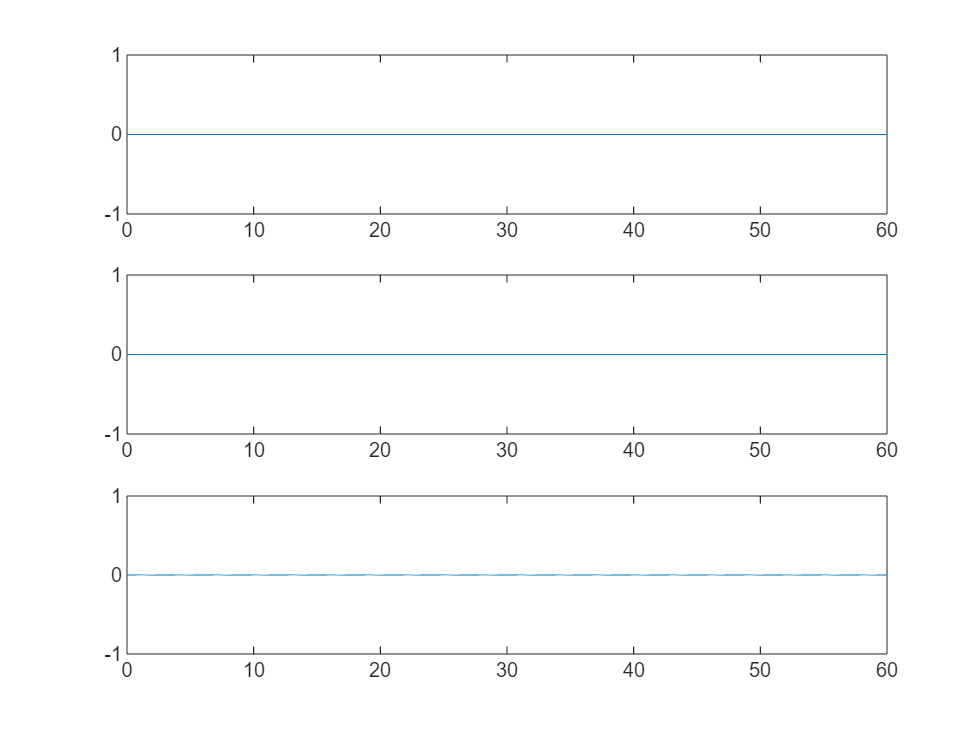

sys = ss(A,B,C,D);
u = zeros(4,size(time,2));
y = lsim(sys,u,time);

figure
subplot(311)
plot(time, y(:,1))
subplot(312)
plot(time, y(:,2))
subplot(313)
plot(time, y(:,3))

real(eig(A))

ans =          0
         0
   -0.0042
         0
   -0.0042
         0
         0
         0
         0
         0


Q = diag([1 1 1 1 1 1 1 1 1 1 1 1]).*1e-4; R = diag([1 1 1 1]).*1e-3;
Klqr = lqr(A,B,Q,R);
Ak = A-B*Klqr;
real(eig(Ak))

ans =   -45.1648
  -45.1648
  -26.3359
   -2.2123
   -2.2123
   -2.6255
   -2.6255
   -1.0005
   -1.0000
   -1.0000


k = C*inv(-Ak)*B;
N = inv(k'*k)*k';

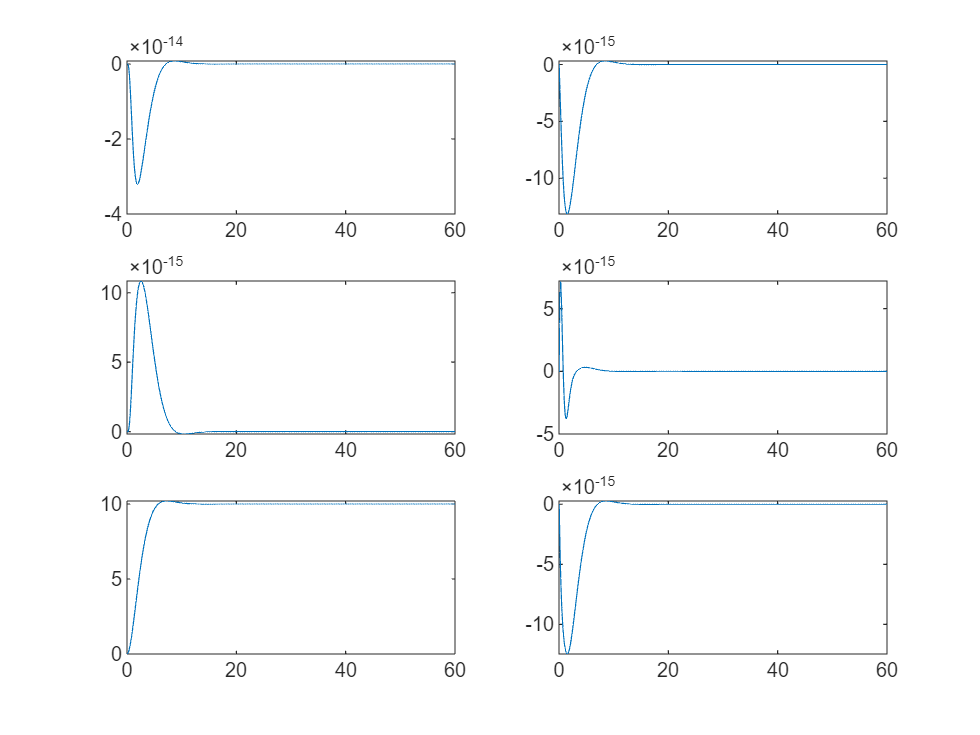

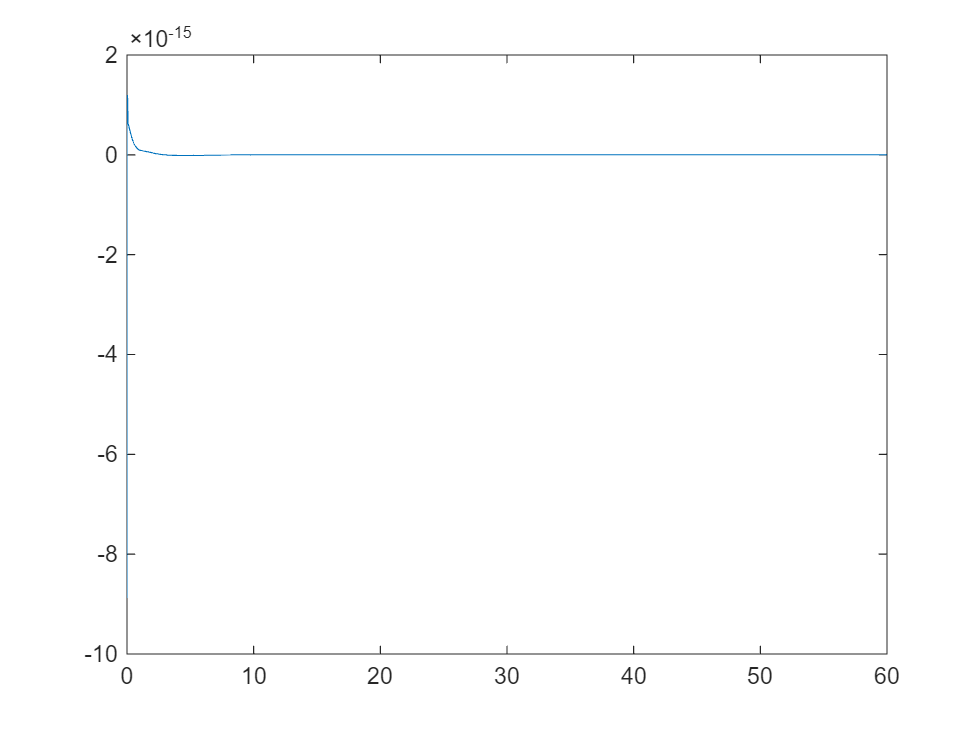

x = zeros(12, size(time,2)); u = zeros(4, size(time,2));
ref = zeros(12,1); ref(3) = 10;
wind = zeros(12,1); wind(3) = 0.01;
for i = 2:size(time,2)
    u(:,i-1) = -Klqr*x(:,i-1) + N*ref;
    xdot = A*x(:,i-1) + B*u(:,i-1);
    x(:,i) = xdot*sample_time + x(:, i-1);
end
figure
subplot(321), plot(time, x(1,:)); subplot(322), plot(time, x(4,:));
subplot(323), plot(time, x(2,:)); subplot(324), plot(time, x(5,:));
subplot(325), plot(time, x(3,:)); subplot(326), plot(time, x(6,:));